% Create a two-dimensional line plot using the plot function. 
syms x
% Create x as a vector of linearly spaced values between -2 and 2.
% Use an increment of 0.04 between the values.
x = -2:0.04:2;
% Define f and g as f and g values of x.
tic
f = sqrt(2.*sqrt(x.^2)-x.^2);
g = -2.14.*sqrt((sqrt(2)-sqrt(abs(x))))

g =          0   -0.2551   -0.3617   -0.4442   -0.5143   -0.5765   -0.6333   -0.6859   -0.7353   -0.7822   -0.8269   -0.8698   -0.9113   -0.9514   -0.9905   -1.0285   -1.0658   -1.1023   -1.1381   -1.1734   -1.2082   -1.2426   -1.2767   -1.3104   -1.3440   -1.3773   -1.4105   -1.4436   -1.4766   -1.5097   -1.5429   -1.5761   -1.6095   -1.6432   -1.6772   -1.7115   -1.7463   -1.7816   -1.8176   -1.8544   -1.8921   -1.9310   -1.9713   -2.0133   -2.0574   -2.1044   -2.1552   -2.2114   -2.2762   -2.3581


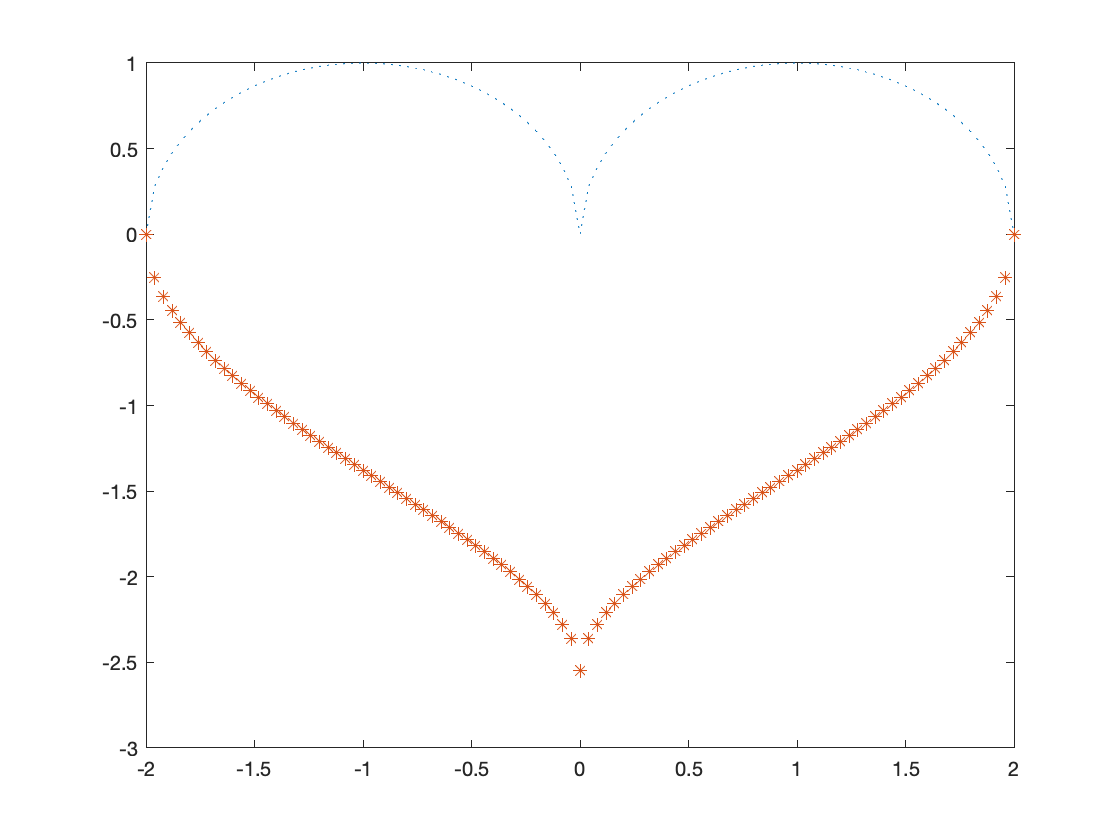

% Create a line plot of both sets of data.
% Specify a dotted line style for the first line and an star line style for the second line.
plot(x,f,':',x,g,'*')

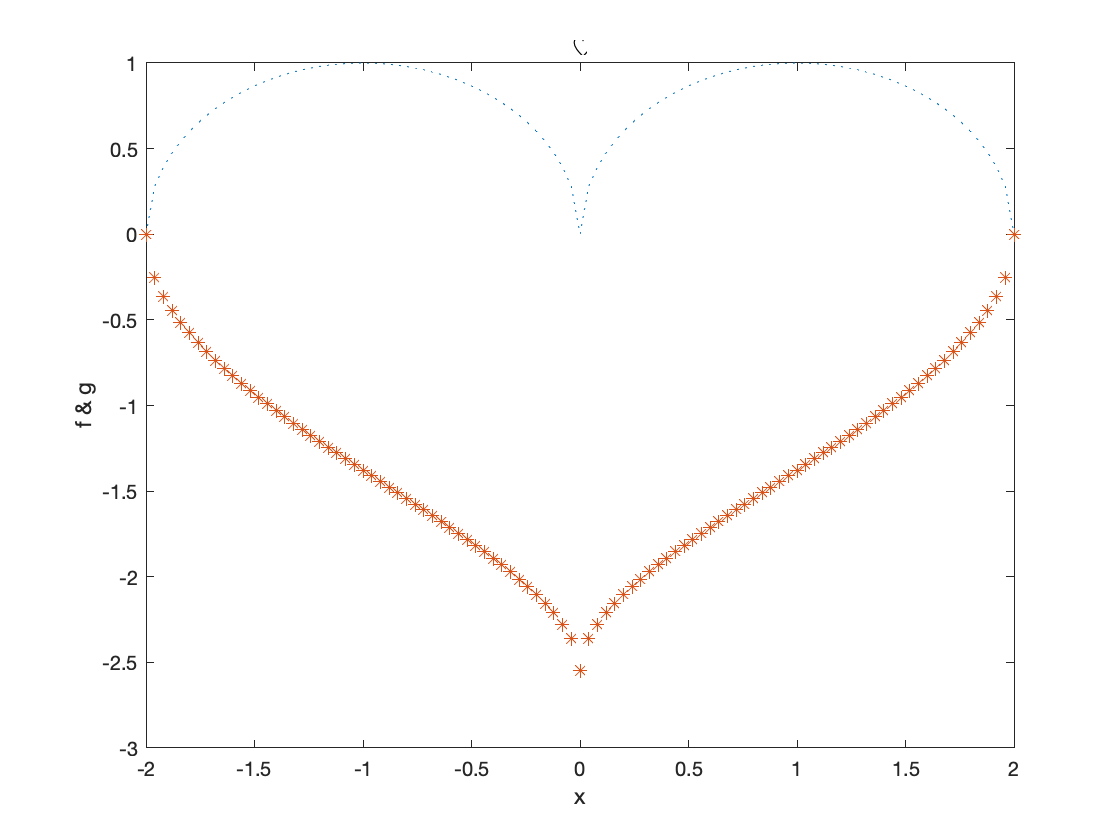

% Label the axes and add a title.
xlabel('x')
ylabel('f & g')
title('♡')

toc

Elapsed time is 0.303041 seconds.


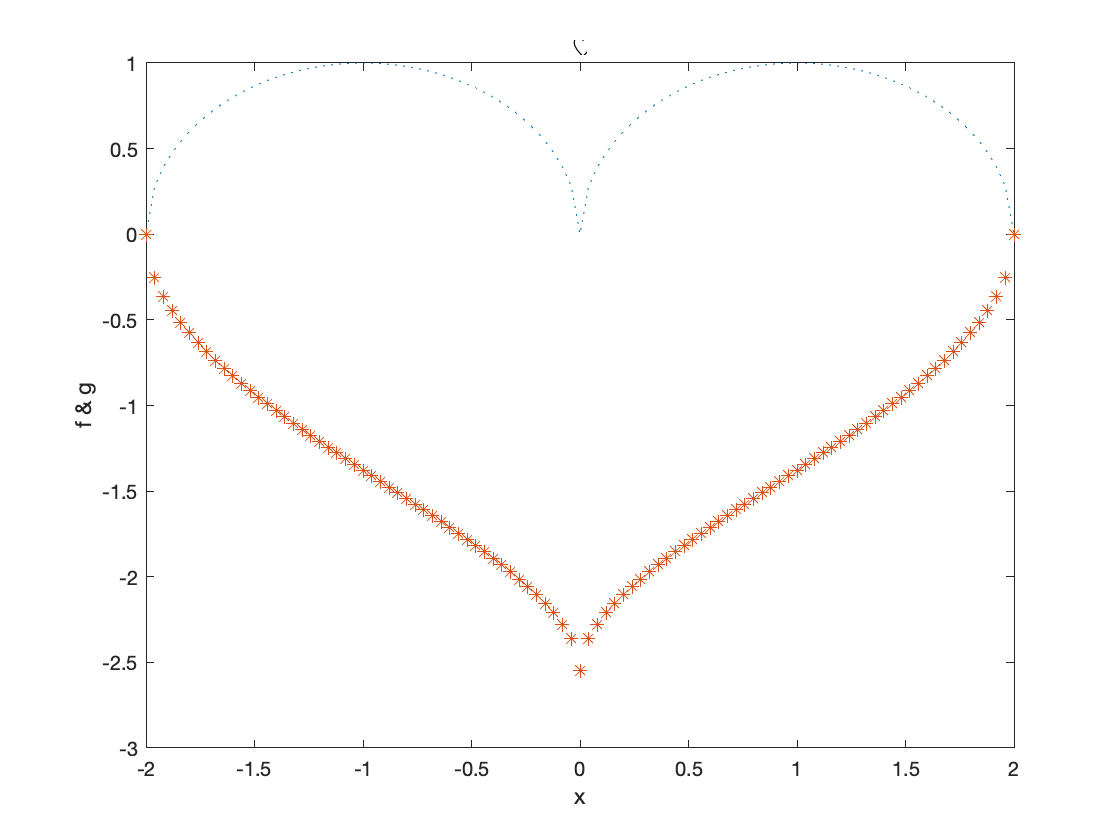

% Save the content in the current figure as an EPS containing vector graphics.
f = gcf;
exportgraphics(f,'vectorfig.eps','ContentType','vector')

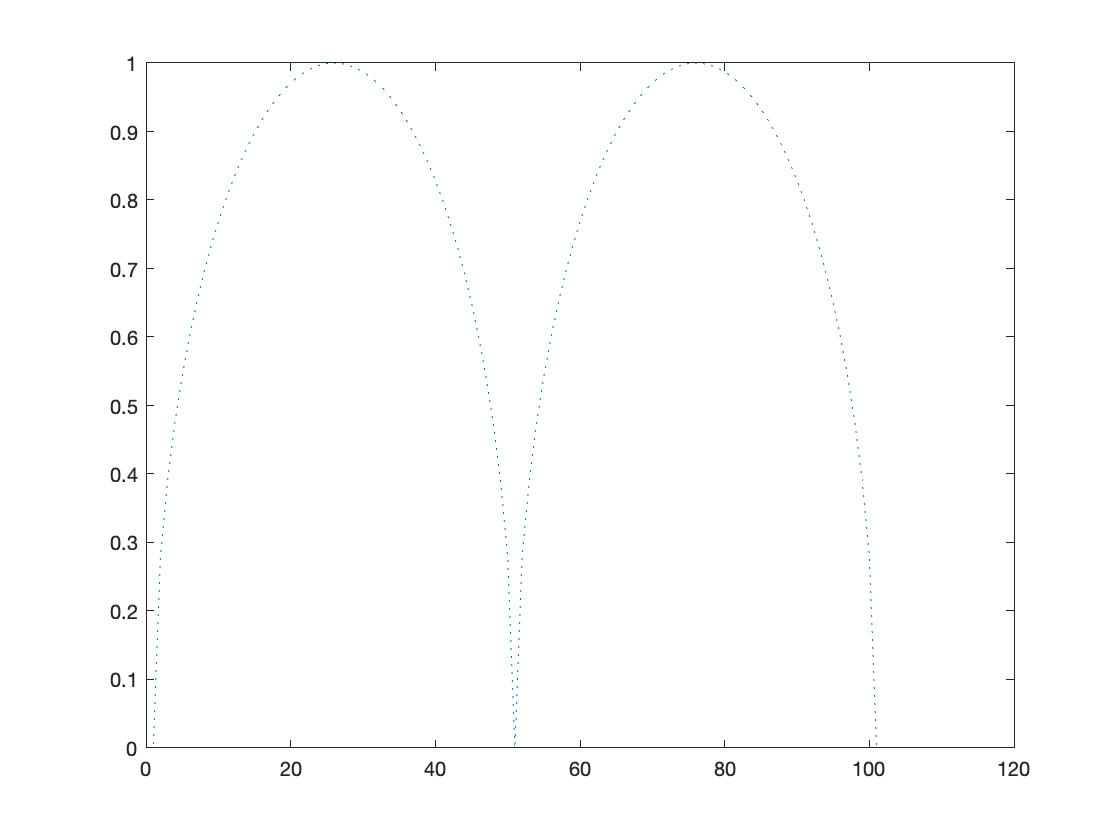

% Preallocate a 101-element vector, and calculate 101 values:
f = ones(1,101);
n = 1;

tic
for x = -2:0.04:2
    f(n) = sqrt(2 * sqrt(x^2)-x^2);
    n = n + 1;
end

plot(f,':')
hold on

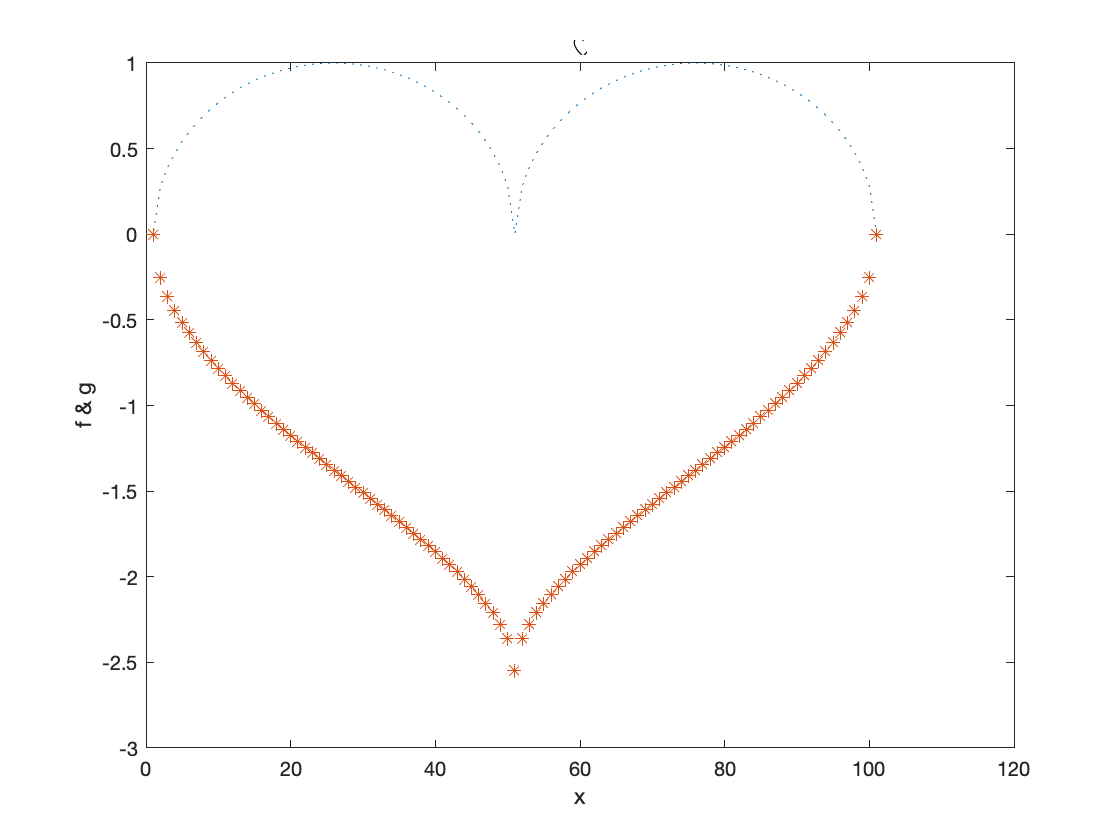

g = ones(1,101);
n = 1;
for x = -2:0.04:2
    g(n) = -2.14 * sqrt((sqrt(2)-sqrt(abs(x))));
    n = n + 1;
end

plot(g,'*')
hold off

xlabel('x')
ylabel('f & g')
title('♡')

toc

Elapsed time is 0.121407 seconds.
